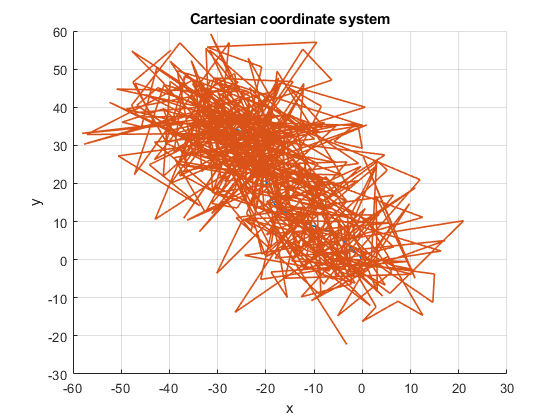

clc
clear
close all

load('GPS.mat');

n=500;
T=1;

v = zeros(2,n);

% Initial coordinates
x = zeros(2,n);

% Random acceleration
var_a = 0.01^2;
a = sqrt(var_a)*randn(2,n);

for i = 2:n
    v(1,i)= v(1,i-1)+a(1,i-1)*T; % V_x
    v(2,i)= v(2,i-1)+a(2,i-1)*T; % V_y
    x(1,i) = x(1,i-1) + v(1,i-1)*T + a(1,i-1)*T^2/2;
    x(2,i) = x(2,i-1) + v(2,i-1)*T + a(2,i-1)*T^2/2;
end

var_eta = 10^2;
eta = randn(2,n)*sqrt(var_eta); 
z = x + eta;

figure
hold on
plot(x(1,:),x(2,:),'linewidth',1.2)
plot(z(1,:),z(2,:),'linewidth',1.2)
title('Cartesian coordinate system')
xlabel('x')
ylabel('y')
grid on

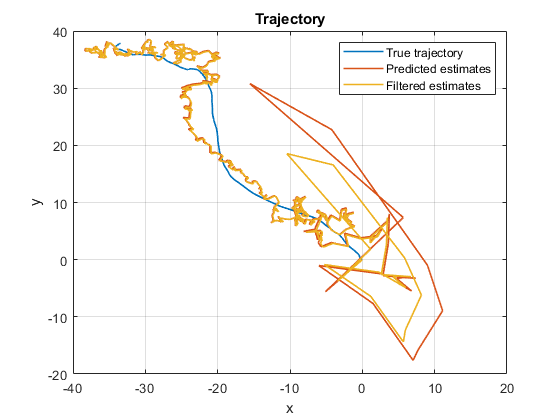


% Transition matrix
phi = eye(4)+ T*diag(ones(3,1),1);
phi(2,3)=0;

% Input matrix
G = [T^2/2 0; T 0; 0 T^2/2;0 T];

% State noise covariance matrix
Q = G*G'*var_a;

% Initial filtered estimate of state vector
X = zeros(4,n);
X(:,1) = [0 0 0 0]'; 

% Initial filtration error covariance matrix 
P = 1e5*eye(4); 

% Measurement noise covariance matrix R
R = var_eta*eye(2);

% Observation matrix
H = eye(4);
H(2:2:4,:) = [];

V = zeros(2,n);

% Algorithm
X_pred = zeros(4,n);
for i = 2:n
    % Prediction
    X_pred(:,i) = phi*X(:,i-1);
    P_pred = phi*P*phi' + Q;
    
    % Filtration 
    K = P_pred*H'*inv(H*P_pred*H'+ R);
    X(:,i) = X_pred(:,i) + K*(z(:,i)-H*X_pred(:,i));
    P = (eye(4)-K*H)*P_pred;
    
    %residual
    V(:,i-1) = z(:,i) - H*X_pred(:,i);
    if V(:,i-1) > (3.5*var_eta)
        P = 1e5*eye(4); 
    end
end

figure
plot(x(1,:),x(2,:),'linewidth',1.2)
hold on
plot(X_pred(1,:),X_pred(3,:),'linewidth',1.2)
plot(X(1,:),X(3,:),'linewidth',1.2)
xlabel('x')
ylabel('y')
legend('True trajectory','Predicted estimates','Filtered estimates')
title('Trajectory')
grid on